# SIM.4. SVF Control of the Coupled Tanks System

h1 = 0 % cm

h1 = 0

h2 = 0 % cm

h2 = 0

g = 981 % cm/s^2

g = 981

d = 4.45 % cm

d = 4.4500

A_1 = (pi*d^2)/4 % cm^2

A_1 = 15.5528

A_2 = A_1 % cm^2

A_2 = 15.5528

d_or = 0.48 % cm

d_or = 0.4800

A_b = (pi*d_or^2)/4 % cm^2

A_b = 0.1810

A_e = A_b % cm^2

A_e = 0.1810

c_1 = A_b*sqrt(2*g)

c_1 = 8.0153

c_2 = A_e*sqrt(2*g)

c_2 = 8.0153

h_10 = 20

h_10 = 20

h_20 = 20

h_20 = 20

A = [-c_1/(2*A_1*sqrt(h_10)) 0; c_1/(2*A_2*sqrt(h_10)) -c_2/(2*A_2*sqrt(h_20))]

A =    -0.0576         0
    0.0576   -0.0576


B = [1/A_1; 0]

B =     0.0643
         0


q_i0 = c_1*sqrt(h_10)  % cm^3/s

q_i0 = 35.8457

con = ctrb(A,B)

con =     0.0643   -0.0037
         0    0.0037


rank(con)

ans = 2

C = [0 1];
ORSys = ss(A,B,C,0);
ORTF = tf(ORSys)

ORTF =
 
          0.003705
  ------------------------
  s^2 + 0.1152 s + 0.00332
 
Continuous-time transfer function.
Model Properties


poles = pole(ORSys)

poles =    -0.0576
   -0.0576


zeros = zero(ORSys)


zeros =

  0×1 empty double column vector



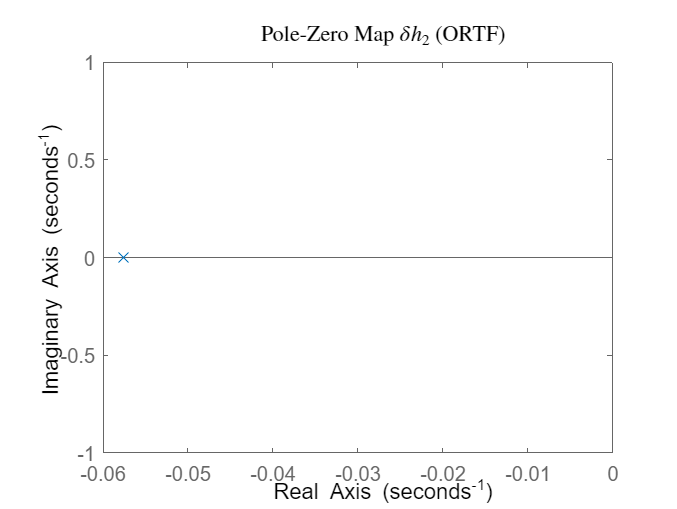

pzmap(ORSys)
title("Pole-Zero Map $\delta h_2$ (ORTF)", "Interpreter", "latex")

C = [1 0];
ORSys = ss(A,B,C,0);
ORTF = tf(ORSys)

ORTF =
 
    0.0643
  -----------
  s + 0.05762
 
Continuous-time transfer function.
Model Properties


poles = pole(ORSys)

poles =    -0.0576
   -0.0576


zeros = zero(ORSys)

zeros = -0.0576

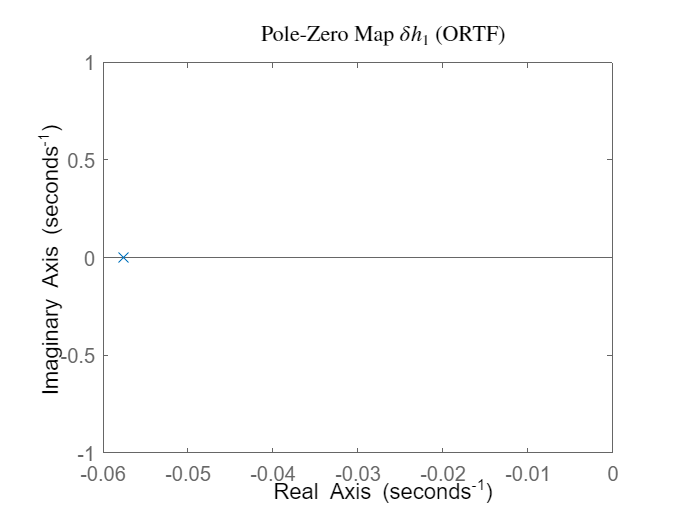

pzmap(ORSys)
title("Pole-Zero Map $\delta h_1$ (ORTF)", "Interpreter", "latex")

w_n = 0.0998  % rad/s

w_n = 0.0998

zeta = 1.0104

zeta = 1.0104

DesPoles = roots([1 2*zeta*w_n w_n^2])

DesPoles =    -0.1153
   -0.0864


K = acker(A,B,DesPoles)

K =     1.3443    0.4480


C = [0 1];
CLSys = ss(A-B*K,B,C,0)

CLSys =
 
  A = 
             x1        x2
   x1   -0.1441   -0.0288
   x2   0.05762  -0.05762
 
  B = 
           u1
   x1  0.0643
   x2       0
 
  C = 
       x1  x2
   y1   0   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


CLTF = tf(CLSys)

CLTF =
 
          0.003705
  ------------------------
  s^2 + 0.2017 s + 0.00996
 
Continuous-time transfer function.
Model Properties


poles = pole(CLSys)

poles =    -0.1153
   -0.0864


zeros = zero(CLSys)


zeros =

  0×1 empty double column vector



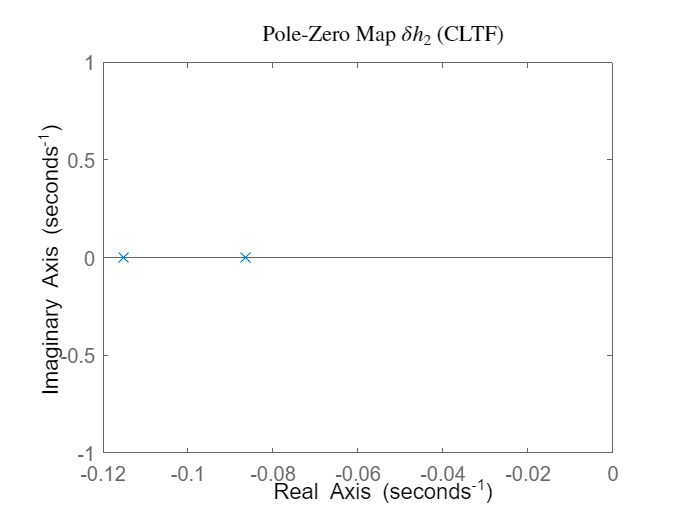

pzmap(CLSys)
title("Pole-Zero Map $\delta h_2$ (CLTF)", "Interpreter", "latex")

C = [1 0];
CLSys = ss(A-B*K,B,C,0)

CLSys =
 
  A = 
             x1        x2
   x1   -0.1441   -0.0288
   x2   0.05762  -0.05762
 
  B = 
           u1
   x1  0.0643
   x2       0
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


CLTF = tf(CLSys)

CLTF =
 
    0.0643 s + 0.003705
  ------------------------
  s^2 + 0.2017 s + 0.00996
 
Continuous-time transfer function.
Model Properties


poles = pole(CLSys)

poles =    -0.1153
   -0.0864


zeros = zero(CLSys)

zeros = -0.0576

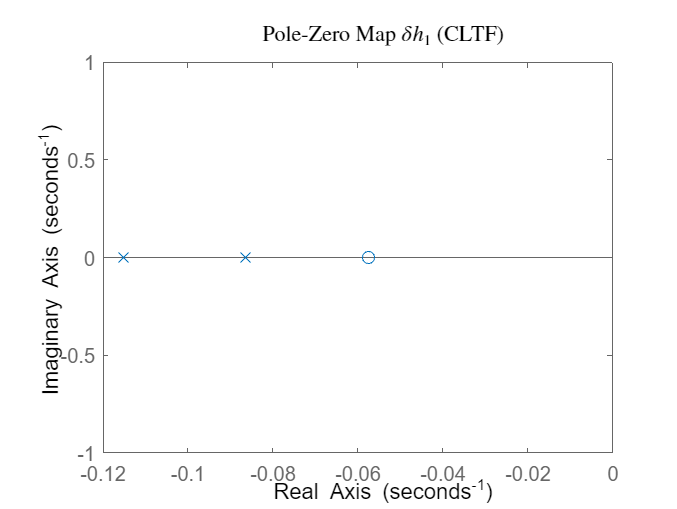

pzmap(CLSys)
title("Pole-Zero Map $\delta h_1$ (CLTF)", "Interpreter", "latex")

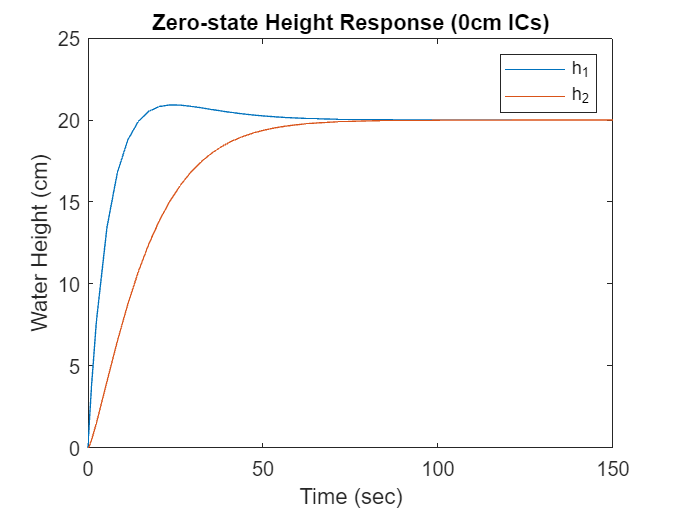

ICs = 0;

out = sim('CTS_Control_Simulink', 150);

figure
plot(out.h1.Time, out.h1.Data)
hold on
plot(out.h2.Time, out.h2.Data)
title("Zero-state Height Response (0cm ICs)")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("h_1", "h_2")

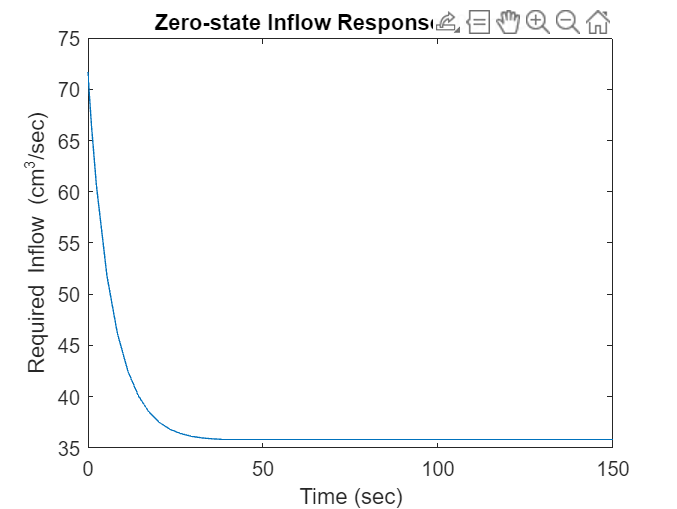


figure
plot(out.q_i.Time, out.q_i.Data)
title("Zero-state Inflow Response (0cm ICs)")
xlabel("Time (sec)")
ylabel("Required Inflow (cm^3/sec)")

out = sim('CTS_Control_Disturbance_Simulink', 200);

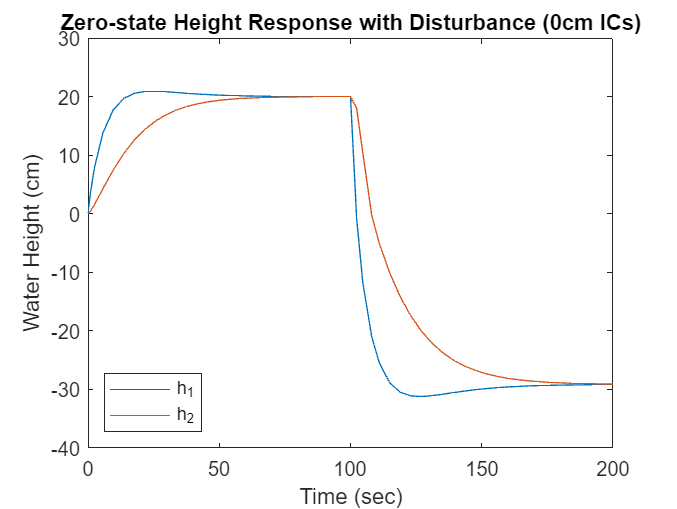


figure
plot(out.h1.Time, out.h1.Data)
hold on
plot(out.h2.Time, out.h2.Data)
title("Zero-state Height Response with Disturbance (0cm ICs)")
xlabel("Time (sec)")
ylabel("Water Height (cm)")
legend("h_1", "h_2", "Location", "southwest")

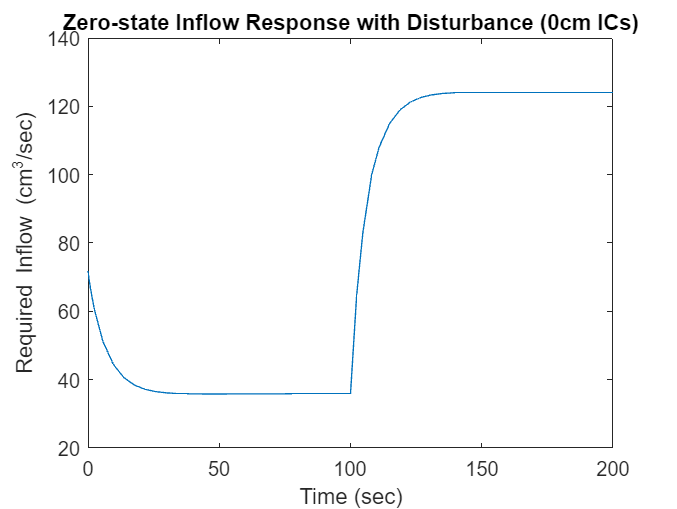


figure
plot(out.q_i.Time, out.q_i.Data)
title("Zero-state Inflow Response with Disturbance (0cm ICs)")
xlabel("Time (sec)")
ylabel("Required Inflow (cm^3/sec)")